# Setup e lettura dati 


cd(fileparts(matlab.desktop.editor.getActiveFilename));
tbl = readtable("misura05.txt", NumHeaderLines=3);
tbl.Properties.VariableNames = ["timestamp", "Ch1", "Ch2"];
t0 = tbl.timestamp(1);
tbl.t = seconds(tbl.timestamp - t0);
tbl.timestamp = [];

sCh1=0.010 * ones(size(tbl.Ch1))+0.0005*tbl.Ch1;
sCh2=0.010 * ones(size(tbl.Ch2))+0.0005*tbl.Ch1;


## Plot dati temporali 

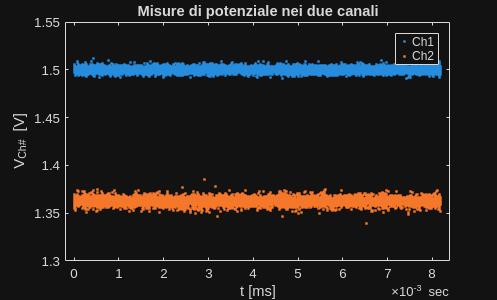


figure;
plot(tbl.t, [tbl.Ch1 tbl.Ch2] ,'.');
title("Misure di potenziale nei due canali");
legend("Ch1","Ch2");
xlabel("t [ms]");
ylabel("V_{Ch#} [V]");

## Funzione gaussiana 


gauss = @(p,x) p(1)* exp(-((x-p(2))./(2*p(3))).^2);



## Istogramma e fit Ch1 


pp1 = [1500, 1.5, 0.001];
dx1 = min(diff(unique(tbl.Ch1)));

figure;

% --- Primo subplot: istogramma + fit ---

h1 = histogram(tbl.Ch1, 'FaceColor', 'r','BinWidth', dx1);

cv1 = h1.BinCounts;
scv1 = sqrt(max(cv1,1));
binCenters1 = h1.BinEdges(1:end-1) + diff(h1.BinEdges)/2;
wcv1 = 1./max(cv1,1);

hold on;
[pph1,R1,J1,CovB1,MSE1] = nlinfit(binCenters1, cv1, gauss, pp1,'Weights',wcv1);

fprintf("pph1 = %.6f\n",pph1);

pph1 = 474.762893
pph1 = 1.500214
pph1 = 0.001619


fprintf("s_pph1 = %.6f\n",sqrt(diag(CovB1)));

s_pph1 = 8.395686
s_pph1 = 0.000032
s_pph1 = 0.000017


MSE1

MSE1 = 1.6125

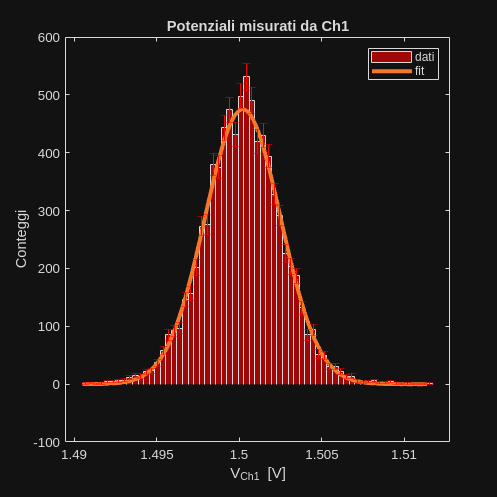


xx1 = linspace(min(tbl.Ch1), max(tbl.Ch1), 1000);
plot(xx1, gauss(pph1, xx1), 'LineWidth', 3);
errorbar(binCenters1, cv1, scv1, "r", 'LineStyle','none');
hold off;

title("Potenziali misurati da Ch1");
xlabel("V_{Ch1} [V]");
ylabel("Conteggi");
legend("dati","fit", "Location","NE");

myfig = gcf; % get current figure
myfig.Position(3:4) = [600 600];
exportgraphics(gcf,"DistribuzioneIN.pdf",ContentType="vector");

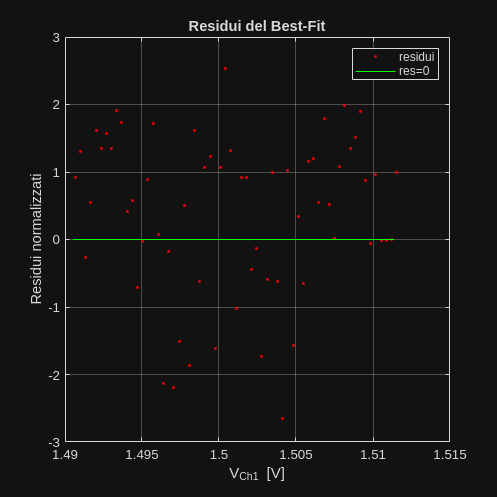


% --- Secondo subplot: residui normalizzati ---

plot(binCenters1,R1 , '.r');
hold on;
plot(xx1, xx1*0, 'g-'); % linea zero
hold off;

title("Residui del Best-Fit");
xlabel("V_{Ch1} [V]");
ylabel("Residui normalizzati");
legend("residui","res=0", "Location","NE");
grid on;

myfig = gcf; % get current figure
myfig.Position(3:4) = [600 600];
exportgraphics(gcf,"DistribuzioneIN_residui.pdf",ContentType="vector");

## Istogramma e fit Ch2

pp2 = [550, 1.3625, 0.0015];
dx2 = min(diff(unique(tbl.Ch2)));

figure;
h2 = histogram(tbl.Ch2, 'FaceColor', 'b','BinWidth', dx2);

cv2 = h2.BinCounts;
scv2 = sqrt(max(cv2,1));
binCenters2 = h2.BinEdges(1:end-1) + diff(h2.BinEdges)/2;
wcv2=1./max(cv2,1)

wcv2 =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.5000    1.0000    1.0000    0.3333    1.0000    0.2500    0.2500    0.3333    0.2500    0.2500    0.2500    0.1429    0.0833    0.1250    0.0588    0.0625    0.0667    0.0526    0.0345



hold on;
[pph2,R2,J2,CovB2,MSE2] = nlinfit(binCenters2, cv2, gauss, pp2,'Weights',wcv2);

fprintf("pph2 = %.6f\n",pph2);

pph2 = 388.773649
pph2 = 1.362415
pph2 = 0.001904


fprintf("s_pph2 = %.6f\n",sqrt(diag(CovB2)));

s_pph2 = 10.008324
s_pph2 = 0.000053
s_pph2 = 0.000031


MSE2

MSE2 = 3.0376

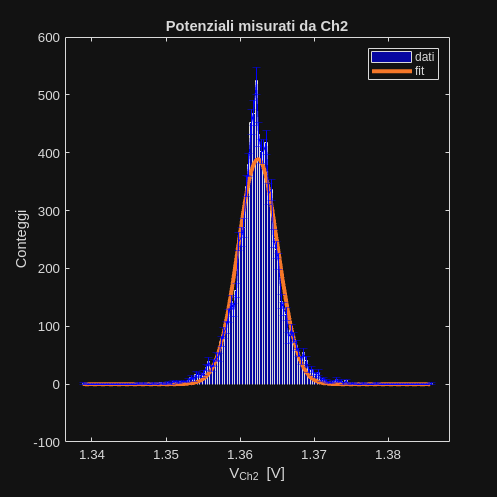



xx2 = linspace(min(tbl.Ch2), max(tbl.Ch2), 1000);
plot(xx2, gauss(pph2, xx2), 'LineWidth', 3);
errorbar(binCenters2,cv2,scv2,"b")
hold off;


title("Potenziali misurati da Ch2");
xlabel("V_{Ch2} [V]");
ylabel("Conteggi");
legend("dati","fit", "Location","NE");

myfig = gcf; % get current figure
myfig.Position(3:4) = [600 600];
exportgraphics(gcf,"DistribuzioneOUT.pdf",ContentType="vector");

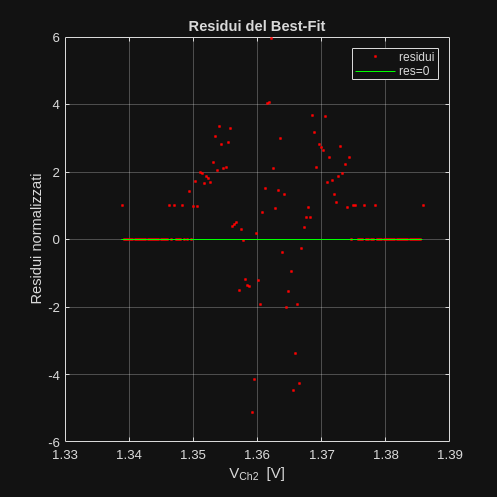



% --- Secondo subplot: residui normalizzati ---

plot(binCenters2,R2 , '.r');
hold on;
plot(xx2, xx2*0, 'g-'); % linea zero
hold off;

title("Residui del Best-Fit");
xlabel("V_{Ch2} [V]");
ylabel("Residui normalizzati");
legend("residui","res=0", "Location","NE");
grid on;

myfig = gcf; % get current figure
myfig.Position(3:4) = [600 600];
exportgraphics(gcf,"DistribuzioneOUT_residui.pdf",ContentType="vector");

##  Fit pesato Ch1 vs Ch2 con nlinfit 


sCh1eff=sqrt(pph1(3)^2+pph2(3)^2)*ones(length(tbl.Ch1),1);
sCh2=pph2(3)*ones(length(tbl.Ch1),1);

%% --- Varianze campionarie punto per punto ---

weights = 1 ./ (sCh1eff.^2);  % vettore di pesi

modelfun = @(b,x) (x .* (1 + b(1)));
beta0 = [0.1];

[mdl,R,J,CovB,MSE] = nlinfit(tbl.Ch2, tbl.Ch1, modelfun, beta0, 'Weights', weights);
mdl

mdl = 0.1011

s_mdl=sqrt(CovB)

s_mdl = 2.3328e-05

MSE

MSE = 1.3245

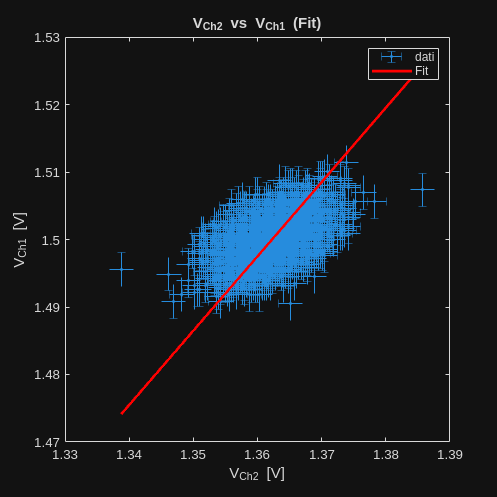


%% --- Plot fit pesato con errorbar ---
figure;
errorbar(tbl.Ch2, tbl.Ch1,sCh1eff,sCh1eff,sCh2,sCh2, '.', 'DisplayName', 'dati'); 
hold on;
xx = linspace(min(tbl.Ch2), max(tbl.Ch2), 1000);
yy = modelfun(mdl, xx);
plot(xx, yy', 'r-', 'LineWidth', 2, 'DisplayName', 'Fit');
hold off;

legend("Location","NE");
title("V_{Ch2} vs V_{Ch1} (Fit)");
xlabel("V_{Ch2} [V]");
ylabel("V_{Ch1} [V]");

%% --- Calcolo chi^2 ridotto ---

myfig = gcf; % get current figure
myfig.Position(3:4) = [600 600];
exportgraphics(gcf,"FitPartitore.pdf",ContentType="vector");


xxx=linspace(min(tbl.Ch2),max(tbl.Ch2),1000)

xxx =     1.3388    1.3388    1.3389    1.3389    1.3390    1.3390    1.3391    1.3391    1.3392    1.3392    1.3392    1.3393    1.3393    1.3394    1.3394    1.3395    1.3395    1.3396    1.3396    1.3397    1.3397    1.3398    1.3398    1.3399    1.3399    1.3400    1.3400    1.3400    1.3401    1.3401    1.3402    1.3402    1.3403    1.3403    1.3404    1.3404    1.3405    1.3405    1.3406    1.3406    1.3407    1.3407    1.3408    1.3408    1.3408    1.3409    1.3409    1.3410    1.3410    1.3411


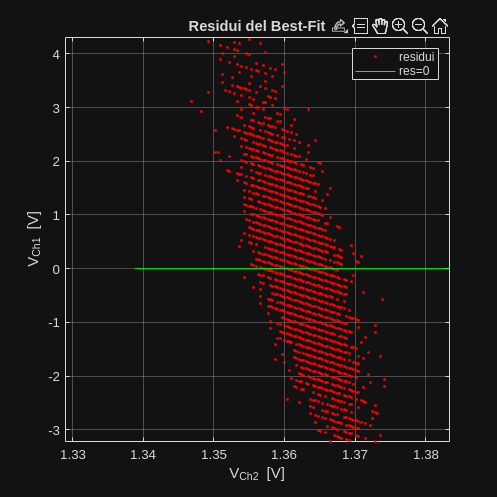

plot(tbl.Ch2,R , '.r');
hold on;
plot(xx2, xx2*0, 'g-'); % linea zero
hold off;


title("Residui del Best-Fit");
xlabel("V_{Ch2} [V]");
ylabel("V_{Ch1} [V]");
legend("residui","res=0", "Location","NE");
grid on;
exportgraphics(gcf,"FitPartitore_residui.pdf",ContentType="vector");